# Comparison of Six Solvers

## Function to Optimize

This example shows how to minimize Rastrigin’s function with six solvers. Each solver has its own characteristics. The characteristics lead to different solutions and run times. The results, examined in , can help you choose an appropriate solver for your own problems.

Rastrigin’s function has many local minima, with a global minimum at (0,0). The function is defined as ${\rm Ras}(x)$:


$${\rm Ras}(x) = 20 + x_1^2 + x_2^2 - 10\left( {\cos 2\pi {x_1} + \cos 2\pi {x_2}} \right).$$


The `rastriginsfcn.m` file, which computes the values of Rastrigin's function, is available when you run this example. This example employs a scaled version of Rastrigin’s function with larger basins of attraction. For information, see [Basins of Attraction](docid:gads#bsbalkx-1). Create a surface plot of the scaled function.

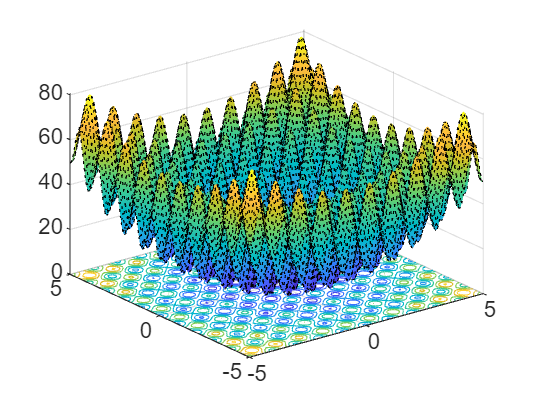

figure;
fsurf(@(x,y)reshape(rastriginsfcn([x(:),y(:)]),size(x)),...
    "MeshDensity",100,...
    "ShowContours","on",...
    "LineStyle",":")

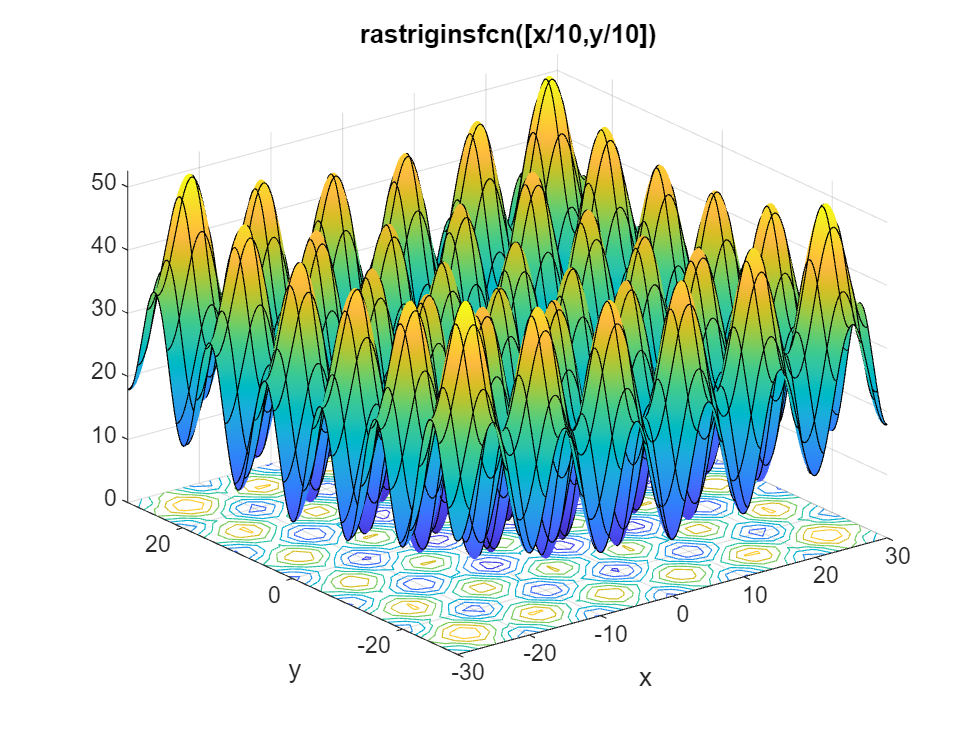


figure;
rf2 = @(x)rastriginsfcn(x/10);
rf3 = @(x,y)reshape(rastriginsfcn([x(:)/10,y(:)/10]),size(x));
fsurf(rf3,[-30 30],'ShowContours','on')
title('rastriginsfcn([x/10,y/10])')
xlabel('x')
ylabel('y')

Usually, you don't know the location of the global minimum of your objective function. To show how the solvers look for a global solution, this example starts all the solvers around the point [20,30], which is far from the global minimum.

This example minimizes `rf2` using the default settings of `fminunc` (an Optimization Toolbox™ solver), `patternsearch`, and `GlobalSearch`. The example also uses `ga` and `particleswarm` with nondefault options to start with an initial population around the point `[20,30]`. Because `surrogateopt` requires finite bounds, the example uses `surrogateopt` with lower bounds of –70 and upper bounds of 130 in each variable.

## Six Solution Methods

### `fminunc`

To solve the optimization problem using the `fminunc` Optimization Toolbox solver, enter:

rf2 = @(x)rastriginsfcn(x/10); % objective
x0 = [20,30]; % start point away from the minimum
[xf,ff,flf,of] = fminunc(rf2,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xf =    19.8991   29.8486


ff = 12.9344

flf = 1

of = struct with fields:
       iterations: 3
        funcCount: 15
         stepsize: 1.7776e-06
     lssteplength: 1
    firstorderopt: 5.9907e-09
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 3.744173e-09, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


- `xf` is the minimizing point.

- `ff` is the value of the objective, `rf2`, at `xf`.

- `flf` is the exit flag. An exit flag of 1 indicates `xf` is a local minimum.

- `of` is the output structure, which describes the `fminunc` calculations leading to the solution.

### `patternsearch`

To solve the optimization problem using the `patternsearch` Global Optimization Toolbox solver, enter:

rf2 = @(x)rastriginsfcn(x/10); % objective
x0 = [20,30]; % start point away from the minimum
[xp,fp,flp,op] = patternsearch(rf2,x0)

patternsearch stopped because the mesh size was less than options.MeshTolerance.


xp =    19.8991   -9.9496


fp = 4.9748

flp = 1

op = struct with fields:
         function: @(x)rastriginsfcn(x/10)
      problemtype: 'unconstrained'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: []
     searchmethod: []
       iterations: 48
        funccount: 174
         meshsize: 9.5367e-07
         rngstate: [1×1 struct]
          message: 'patternsearch stopped because the mesh size was less than options.MeshTolerance.'


- `xp` is the minimizing point.

- `fp` is the value of the objective, `rf2`, at `xp`.

- `flp` is the exit flag. An exit flag of 1 indicates `xp` is a local minimum.

- `op` is the output structure, which describes the `patternsearch` calculations leading to the solution.

### `ga`

To solve the optimization problem using the `ga` Global Optimization Toolbox solver, enter:

rng default % for reproducibility
rf2 = @(x)rastriginsfcn(x/10); % objective
x0 = [20,30]; % start point away from the minimum
initpop = 10*randn(20,2) + repmat(x0,20,1);
opts = optimoptions('ga','InitialPopulationMatrix',initpop);

- `initpop` is a 20-by-2 matrix. Each row of `initpop` has mean `[20,30]`, and each element is normally distributed with standard deviation 10. The rows of initpop form an initial population matrix for the `ga` solver.

- `opts` is the options that set `initpop` as the initial population.

- ga uses random numbers, and produces a random result.

- The next line calls `ga`, using the options.

[xga,fga,flga,oga] = ga(rf2,2,[],[],[],[],[],[],[],opts)

ga stopped because it exceeded options.MaxGenerations.


xga =    -0.0042   -0.0024


fga = 4.7054e-05

flga = 0

oga = struct with fields:
      problemtype: 'unconstrained'
         rngstate: [1×1 struct]
      generations: 200
        funccount: 9453
          message: 'ga stopped because it exceeded options.MaxGenerations.'
    maxconstraint: []
       hybridflag: []


- `xga` is the minimizing point.

- `fga` is the value of the objective, `rf2`, at `xga`.

- `flga` is the exit flag. An exit flag of 0 indicates that `ga` reaches a function evaluation limit or an iteration limit. In this case, `ga` reaches an iteration limit.

- `oga` is the output structure, which describes the `ga` calculations leading to the solution.

### `particleswarm`

Like `ga`, `particleswarm` is a population-based algorithm. So for a fair comparison of solvers, initialize the particle swarm to the same population as `ga`.

rng default % for reproducibility
rf2 = @(x)rastriginsfcn(x/10); % objective
opts = optimoptions('particleswarm','InitialSwarmMatrix',initpop);
[xpso,fpso,flgpso,opso] = particleswarm(rf2,2,[],[],opts)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


xpso =     9.9496    0.0000


fpso = 0.9950

flgpso = 1

opso = struct with fields:
      rngstate: [1×1 struct]
    iterations: 56
     funccount: 1140
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []


### `surrogateopt`

`surrogateopt` does not require a start point, but does require finite bounds. Set bounds of –70 to 130 in each component. To have the same sort of output as the other solvers, disable the default plot function.

rng default % for reproducibility
lb = [-70,-70];
ub = [130,130];
rf2 = @(x)rastriginsfcn(x/10); % objective
opts = optimoptions('surrogateopt','PlotFcn',[]);
[xsur,fsur,flgsur,osur] = surrogateopt(rf2,lb,ub,opts)

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


xsur =     9.9494   -9.9502


fsur = 1.9899

flgsur = 0

osur = struct with fields:
        elapsedtime: 12.9666
          funccount: 200
    constrviolation: 0
               ineq: [1×0 double]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


- `xsur` is the minimizing point.

- `fsur` is the value of the objective, `rf2`, at `xsur`.

- `flgsur` is the exit flag. An exit flag of 0 indicates that `surrogateopt` halted because it ran out of function evaluations or time.

- `osur` is the output structure, which describes the `surrogateopt` calculations leading to the solution.

### `GlobalSearch`

To solve the optimization problem using the `GlobalSearch` solver, enter:

rf2 = @(x)rastriginsfcn(x/10); % objective
x0 = [20,30]; % start point away from the minimum
problem = createOptimProblem('fmincon','objective',rf2,...
    'x0',x0);
gs = GlobalSearch;

`problem` is an optimization problem structure. `problem` specifies the `fmincon` solver, the `rf2` objective function, and `x0=[20,30]`. For more information on using `createOptimProblem`, see [Create Problem Structure](docid:gads#bsc5960).

**Note**: You must specify `fmincon` as the solver for `GlobalSearch`, even for unconstrained problems.

`gs` is a default `GlobalSearch` object. The object contains options for solving the problem. Calling `run(gs,problem)` runs problem from multiple start points. The start points are random, so the following result is also random.

[xg,fg,flg,og] = run(gs,problem)

GlobalSearch stopped because it analyzed all the trial points.

All 7 local solver runs converged with a positive local solver exit flag.


xg = 1.0e-07 *

   -0.1405   -0.1405


fg = 0

flg = 1

og = struct with fields:
                funcCount: 2217
         localSolverTotal: 7
       localSolverSuccess: 7
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'GlobalSearch stopped because it analyzed all the trial points.↵↵All 7 local solver runs converged with a positive local solver exit flag.'


- `xg` is the minimizing point.

- `fg` is the value of the objective, `rf2`, at `xg`.

- `flg` is the exit flag. An exit flag of 1 indicates all `fmincon` runs converged properly.

- `og` is the output structure, which describes the `GlobalSearch` calculations leading to the solution.

### Compare Syntax and Solutions

One solution is better than another if its objective function value is smaller than the other. The following table summarizes the results.

sols = [xf;
    xp;
    xga;
    xpso;
    xsur;
    xg];
fvals = [ff;
    fp;
    fga;
    fpso;
    fsur;
    fg];
fevals = [of.funcCount;
    op.funccount;
    oga.funccount;
    opso.funccount;
    osur.funccount;
    og.funcCount];
stats = table(sols,fvals,fevals);
stats.Properties.RowNames = ["fminunc" "patternsearch" "ga" "particleswarm" "surrogateopt" "GlobalSearch"];
stats.Properties.VariableNames = ["Solution" "Objective" "# Fevals"];
disp(stats)

                              Solution             Objective     # Fevals
                     __________________________    __________    ________

    fminunc               19.899         29.849        12.934        15  
    patternsearch         19.899        -9.9496        4.9748       174  
    ga                -0.0042178     -0.0024347    4.7054e-05      9453  
    particleswarm         9.9496       6.75e-07       0.99496      1140  
    surrogateopt          9.9494        -9.9502        1.9899       200  
    GlobalSearch     -1.4046e-08    -1.4046e-08             0      2217  



These results are typical:

- `fminunc` quickly reaches the local solution within its starting basin, but does not explore outside this basin at all. `fminunc` has a simple calling syntax.

- `patternsearch` takes more function evaluations than fminunc, and searches through several basins, arriving at a better solution than `fminunc`. The `patternsearch` calling syntax is the same as that of `fminunc`.

- `ga` takes many more function evaluations than patternsearch. By chance it arrives at a better solution. In this case, `ga` finds a point near the global optimum. `ga` is stochastic, so its results change with every run. `ga` has a simple calling syntax, but there are extra steps to have an initial population near `[20,30]`.

- `particleswarm` takes fewer function evaluations than `ga`, but more than `patternsearch`. In this case, `particleswarm` finds a point with lower objective function value than `patternsearch`, but higher than `ga`. Because `particleswarm` is stochastic, its results change with every run. `particleswarm` has a simple calling syntax, but there are extra steps to have an initial population near `[20,30]`.

- `surrogateopt` stops when it reaches a function evaluation limit, which by default is 200 for a two-variable problem. `surrogateopt` has a simple calling syntax, but requires finite bounds. `surrogateopt` attempts to find a global solution, but in this case does not succeed. Each function evaluation in `surrogateopt` takes a longer time than in most other solvers, because `surrogateopt` performs many auxiliary computations as part of its algorithm.

- `GlobalSearch` `run` takes the same order of magnitude of function evaluations as `ga` and `particleswarm`, searches many basins, and arrives at a good solution. In this case, `GlobalSearch` finds the global optimum. Setting up `GlobalSearch` is more involved than setting up the other solvers. As the example shows, before calling `GlobalSearch`, you must create both a `GlobalSearch` object (`gs` in the example), and a problem structure (`problem`). Then, you call the `run` method with `gs` and `problem`. For more details on how to run `GlobalSearch`, see [Workflow for GlobalSearch and MultiStart](docid:gads#bsc7jsm).

*Copyright 2021 The MathWorks, Inc.*